# **Experimental Modal Analysis(EMA):**     A **SISO** Cantilever Vibration Analysis

In the following script we'll **analyze some time series data** collected from a **SIMO** Vibration experiment conducted on a **Cantilever**. 

## **Objective:**

- Convert the simulation times series measurements into **Frequency Response Functions** **(FRFs)**

- Extract the **Modal properties** ($\omega_n \;,\zeta_n$) from the **FRF**.

We'll use MATLAB's functions:

- [`modalfrf()`](matlab:  doc modalfrf)` , `[`modalsd()`](matlab:  doc  modalsd)` , `[`modalfit()`](matlab:  doc  modalfit) 

## **Background:   Part_1 - The parametric FRF equation for a Mechanical system**

Recall the parametric equation of a Frequency Response Function (FRF) of a Mechanical structure:

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\frac{R_k }{s-\lambda_k }\;\;+\;\;\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;e\;\;+\;\;\;\;\frac{f}{s^2 }\right.$$
          

where we have:

- **MODAL poles**:       $\lambda_k \;\;\;=\;-\zeta_k \ldotp \omega_{n_k } \;\;\;+\;\;\;j\ldotp \omega_{n_k } \ldotp \sqrt{\;1\;-{\zeta_k }^2 \;}$

- **RESIDUES**:            $R_k$

## **Background:   Part_2 - The Modal properties extraction process**

Our **Modal Fitting** process can be summarized by the following workflow pipeline:

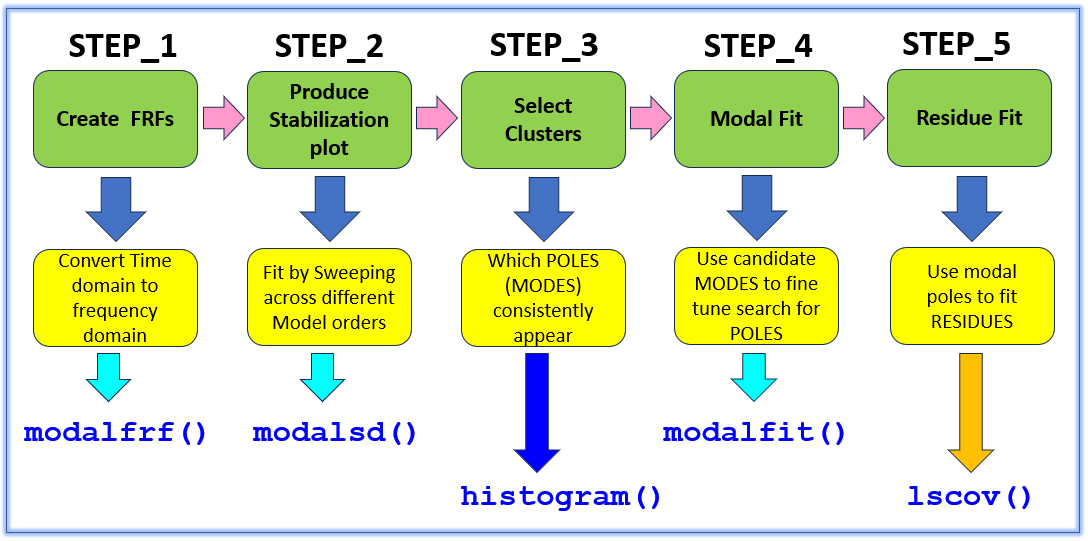

## **Background:   Part_3 - Where did our time series data come from**

- The DATA:

- The timeseries data that we'll be analyzing is stored in the EXCEL file `MEAS_CANTIL_01_shaker_T_F_v2_to_v21.xls`

- The MODEL:

- The timeseries data analyzed in this script was generated by a 20-element **Finite Element model** of a cantilever.  This** simulated time series data** was created by the file [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open  APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx)

- The EXCITATION:

- The excitation Force applied to the cantilever was a **Band Limited Random Noise force** applied via a **SHAKER**.

- The shaker force was applied at **Node 6** of the cantilever and was applied in the **vertical (Y-axis) direction**

- The RESPONSE:

- We measured the **transverse** **displacements** at **20** locations along the cantilever, i.e.:  $\left\lbrace v_2 \;\;,\;v_3 \;\;,v_4 \;\;,v_5 \;\;,\;\ldotp \ldotp \ldotp ,\;v_{19} \;\;,v_{20} \;\;,\;v_{21} \right\rbrace$

- You'll get to select ONE of these to analyze.

- Miscellaneous

- In this script we'll **analyze just ONE of the response measurements** (hence **SISO**) .... but after reviewing the workflows presented here, why not look at the SIMO analysis done in the file [`bh_EXPLORE_EMA_Task_02_cantilever_SIMO.mlx`](matlab:  open bh_EXPLORE_EMA_Task_02_cantilever_SIMO.mlx)` - `where we also extract MODE shapes.

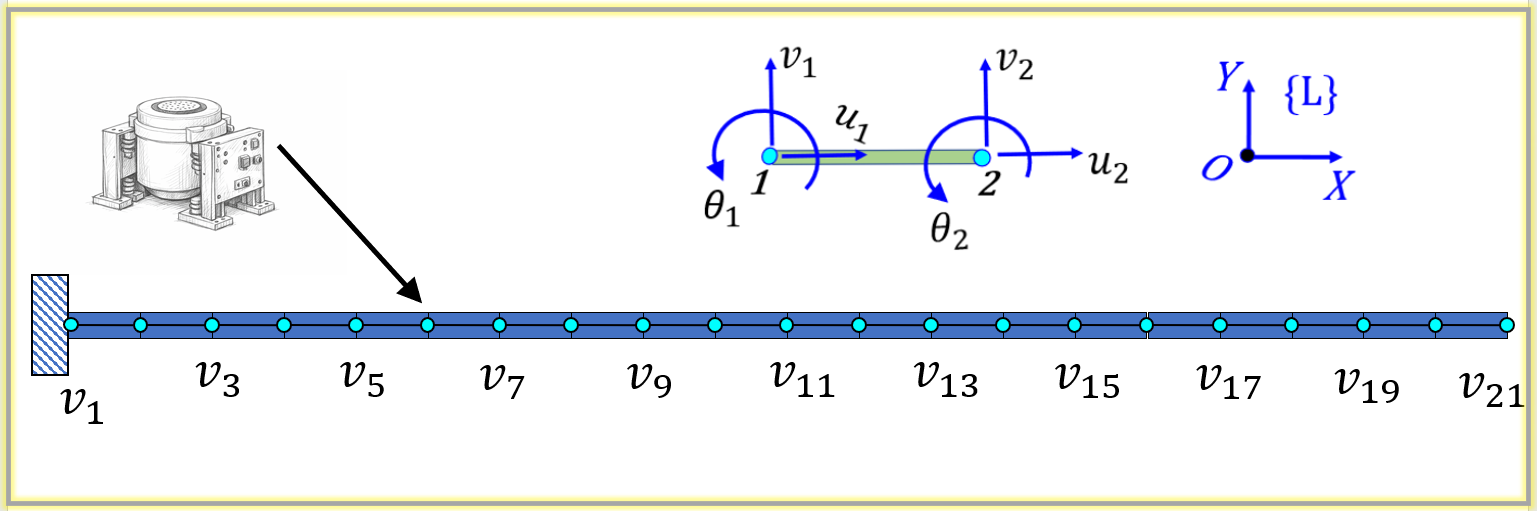

## **Analytic Modal frequencies, FEM Modal frequencies and Mode shapes:**

For the cantilever presented in [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open  APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx)`, `the first 4 analytic natural frequencies of ***bending*** vibration computed using **Engineering Beam Theory,**  are listed in column_A of **Table(1) below**.  Column_B of Table(1) summarizes the modes computed from the 20 element **FE model** of the cantilever (i.e.: a  60-dof model representing transverse and axial dynamics). Note that the first 4-modes predicted by the FE model are within 0.01 Hz of the analytic beam theory modes. For calculation details see:

- [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open  APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx)

- [`bh_cantil_analytic_modes()`](matlab:  open  bh_cantil_analytic_modes)

**Table(1): **  Analytic Bending modes and FE model modes. 

## **BONUS Round:**

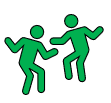 Extracting MODAL properties from measured FRFs is an example of a more general problem referred to as "**System Identification**" (aka SYS ID).  MATLAB has a dedicated library of algorithms for doing SYS ID - the [**System Identification toolbox**](https://www.mathworks.com/help/releases/R2025b/ident/index.html).  So ? - So let's also use a couple of the functions from the  System Identification toolbox to create a model and then extract our modal properties. Specifically we'll look at these functions

- [`frd()`](matlab: doc frd) , [`ssest()`](matlab: doc ssest)`, `[`tfest()`](matlab: doc tfest)`, `[`n4sid()`](matlab: doc n4sid)

## RESOURCES:

The following Appendix files are useful for some background knowledge:

- [`APPENDIX_00_Matrix_Algebra_Essentials_for_Modal.mlx`](matlab:  open bh_Modal.APPENDIX_00_Matrix_Algebra_Essentials_for_Modal)  

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)    

- [`APPENDIX_03_Signal_things.mlx `](matlab:  open  bh_Modal.APPENDIX_03_Signal_things)           

- [`APPENDIX_04_tf_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_04_tf_and_frf)

- [`APPENDIX_05_irf_and_fft_and_frf.mlx`](matlab:  open bh_Modal.APPENDIX_05_irf_and_fft_and_frf)

- [`APPENDIX_06_PHASE_PLOTS.mlx`](matlab:  open bh_Modal.APPENDIX_06_PHASE_PLOTS)

- [`APPENDIX_07_NATURAL_DAMPED_and_RESONANT.mlx`](matlab:  open bh_Modal.APPENDIX_07_NATURAL_DAMPED_and_RESONANT)

- [`APPENDIX_08_explore_pulse.mlx`](matlab:  open bh_Modal.APPENDIX_08_explore_pulse)

`Bradley Horton:  bhorton@mathworks.com`

# Load in the FULL Time Series measurement data set

Clear your workspace

clear

Recall that our time series data was generated in the script [`APPENDIX_A_SIMO_CANTILEVER_create_dataset.mlx`](matlab:  open APPENDIX_A_SIMO_CANTILEVER_create_dataset)

MEAS_tseries_tab = readtable("MEAS_CANTIL_01_shaker_T_F_v2_to_v21.xlsx");

whos MEAS_tseries_tab

Have a peak at the FULL measurement data set

head(MEAS_tseries_tab)

## Select ONE Response Channel

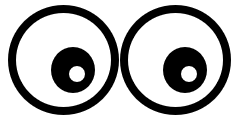 For this **SISO analysis** ... we need to select ONE response channel.  So make your choice from the drop-box below.  **NOTE:** there is NO "`v_1`" ... because that is the clamped boundary condition i.e.: $v_1 =0$

THE_RESPONSE_CHANNEL_LABEL = "v_6";
MEAS_tseries_tab = MEAS_tseries_tab(:, ["t","F", THE_RESPONSE_CHANNEL_LABEL]);
vdof_labels_list = MEAS_tseries_tab.Properties.VariableNames(3);
vdof_labels_list = string(vdof_labels_list)

Have a peak at the measurement data that we've retained

whos MEAS_tseries_tab

head(MEAS_tseries_tab)

## Set up some Signal processing parameters:

Our Excitation FORCE was made up of a **Band Limited Random Noise** signal. So in preparation for computing the Frequency Response Functions(FRFs) we'll use a Hann window for both the excitations and response channels

- See the DOC [`hann()`](matlab:  doc hann)

- The windowing variables will be used by [`modalfrf()`](matlab:  doc modalfrf)

Fs_hz       = 1/(MEAS_tseries_tab.t(2) - MEAS_tseries_tab.t(1))
NUM_WINDOWS = 5;
tmp_win_N   = floor( height(MEAS_tseries_tab) / NUM_WINDOWS );  
THE_WINDOW  = hann(tmp_win_N);
n_OVERLAP   = 0;  %floor(tmp_win_N/2);

Pull out the input(FORCE) and response(DISPLACEMENTS) data

in_col    = MEAS_tseries_tab.F;      % EXCITATION - the INPUT
out_col   = MEAS_tseries_tab{:, 3};  % RESPONSE   - the OUTPUT

whos in_col  out_col

# Visualize the **timeseries** Measurements:

figure;
tiledlayout(2,1);

hax(1) = nexttile;
    plot(MEAS_tseries_tab.t, in_col, '-b.'); grid on; xlabel("Time (secs)"); ylabel("Force (N)");
        title("Measured:  Force (N)");

hax(2) = nexttile;
    plot(MEAS_tseries_tab.t, out_col, '-r.'); grid on; xlabel("Time (secs)"); ylabel("pos (m)");
        title("Measured:  pos (m)  @ sensorID="+vdof_labels_list);   

linkaxes(hax,"x") % link axes for ZOOMING

# Visualize the **Frequency content** of the Excitation **FORCE**:

Over what bandwidth were we able to excite the structure ?

LOC_plot_FORCE_spectrum( (1/Fs_hz), in_col, THE_WINDOW)   

# **Step_1:**   Estimate the System **FRF** from our timeseries Measurements:

Let's convert our timeseries data into **Frequency Response Functions** (FRFs)

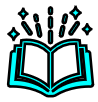 **DOC**:   see [`modalfrf()`](matlab:  doc modalfrf)

[all_frf, all_f, tmp_coh] = modalfrf( in_col, out_col, Fs_hz, ...
                                      THE_WINDOW, n_OVERLAP,  ...
                                       Sensor="dis");

whos  all_frf  all_f

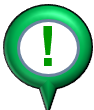 **NOTE:**  the frequency vector `all_f` (in Hz) that is returned only includes frequencies up to the NYQUIST frequency

all_f(end)

## Visualize the MEASURED (estimated) FRF

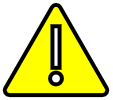 Assert that our FRF variable only has 1 column

assert(1==size(all_frf,2), "###_ERROR:  Hey - we're doing a SISO analysis ... why are there more than 1 FRFs ?");

**Define some data containers for storing these estimated FRFs:**

meas.frf       = all_frf;
meas.coh       = tmp_coh;   % understood will be NaN IFFF only 1 window block used
meas.f_hz      = all_f; 
meas.w         = 2*pi*meas.f_hz;
meas.frf_dB    = 20*log10(abs(meas.frf));
meas.phase_deg = rad2deg(  angle(meas.frf)   );

#### Specify the Frequency range of interest

Let's also select a frequency range of interest that we'll focus on when we eventually do the fitting task (later in this script)

-  **TIP:**  choose a frequency range that is well excited by your EXCITATION force.

roi.range_Hz = [0, 150];

tmp_ind      = find( (meas.f_hz > roi.range_Hz(1)) & (meas.f_hz < roi.range_Hz(2))  );

roi.f_Hz     = meas.f_hz(tmp_ind);
roi.frf      = meas.frf(tmp_ind, :);
roi.coh      = meas.coh(tmp_ind, :);

#### And plot the Measured (estimated) FRFs

figure;
      hax(1) = subplot(2,1,1); 
       yyaxis left
           plot(roi.f_Hz, 20*log10( abs(roi.frf)), "-b.", "DisplayName","MEAS")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(dB)");
       yyaxis right
           plot(roi.f_Hz, roi.coh, "-m.", "DisplayName","COH")
               grid on; axis tight
               xlabel("(Hz)");   ylabel("(Coherance)");

               title("Measured FRF for RESPONSE channel $\Longrightarrow("+vdof_labels_list+")$", "FontName","Courier", "Interpreter","latex")
      hax(2) = subplot(2,1,2); 
           plot(roi.f_Hz, rad2deg( angle(roi.frf) ), "-b.")
               grid on; axis tight
               xlabel("(Hz)");  ylabel("(degrees)")

      linkaxes(hax,"x") % link axes for ZOOMING

# **STEP_2:**    Produce Stabilization plot

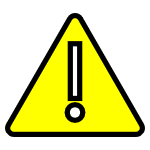 **NOTE:  **for this Cantilever data set .. the LSRF method can be sooooo slow ...So I recommend you do NOT select that.

try_it_FitMethod = "lsce";

### Consider the Stabilization diagram

Let's sweep across a variety of model ORDERS ... and extract fitted the fitted modes and plot them on a Stabilization diagram

 **DOC**:   see  [`modalsd()`](matlab:  doc  modalsd)

We'll use ALL of our FRF channels

MAXMODES = 30;

figure   %  the STABILIZATION plot
    fn_sd = modalsd( meas.frf, meas.f_hz, Fs_hz, ...
                     MaxModes=MAXMODES, ...
                     FreqRange=roi.range_Hz, ...
                     FitMethod=try_it_FitMethod)


Maybe we weren't able to sweep across the desired MAX modes

ACTUAL_MAXMODES = size(fn_sd, 2);  

Remove NaNs and ZEROS

FN_HZ_ALL          =   rmmissing(fn_sd(:));
tmp_ind            =  FN_HZ_ALL == 0;
FN_HZ_ALL(tmp_ind) = [];

# **STEP_3:**   Look for Clusters from the Stabilization plot

 REMEMBER: many of the modes will NOT be real modes, rather they will be computational ones that we need to ignore.  So let's utilize a **histogram** to semi automate where we think the real modes are.  We will need to tune this, e.g.:  

- the histogram **bin width** may need some "trial/error" tuning.

- the **minimum number of counts** within a bin may need some "trial/error" tuning.

See:  [`bh_collect_by_histogram()`](matlab:  open bh_collect_by_histogram)

hist_DF_bin                = 1; %1; %0.2; %0.25; % (Hz)
hist_MIN_REQUIRED_COUNTS   = floor(0.75*ACTUAL_MAXMODES);

hist_fHz_range             = roi.range_Hz;

my_fhz_list_FROM_HIST = bh_collect_by_histogram(FN_HZ_ALL, hist_DF_bin, hist_MIN_REQUIRED_COUNTS, hist_fHz_range);

So our candidate resonant frequencies are:

my_fhz_list_FROM_HIST

# **STEP_4:**   Extract our Modal Poles

So from the stabilization diagram, how many modes do you think we should try and fit ?

-  **NOTE:** We'll specify a HIGHER target number of modes to fit ... Overspecifying the number of modes gives better (?) results.

NUM_MODES_TO_FIT = 10

Now do a MODAL fit:

- see DOC for [`modalfit()`](matlab:  doc  modalfit) 

- **NOTE: ** We'll specify the frequencies extracted from our histogram and pass these into [`modalfit()`](matlab:  doc  modalfit) as 'PhysFreq'.  

[fn,dr,ms] = modalfit( meas.frf, meas.f_hz, Fs_hz, ...
                       NUM_MODES_TO_FIT, ...
                       PhysFreq=my_fhz_list_FROM_HIST, ...
                       FreqRange=roi.range_Hz, ...
                       FitMethod=try_it_FitMethod);

Remove any Nans:

tmp_ind  = ~isnan(fn) & ~isnan(dr);

fn_clean = fn(tmp_ind);
dr_clean = dr(tmp_ind);

Define the system poles (Half of the poles)

- 
$$\lambda \;\;=\;\;-\zeta \ldotp \omega_n \;\;+\;\;j\ldotp \omega_n \ldotp \sqrt{1\;\;-\;\zeta^2 \;\;\;}$$


lambda_clean = -1*(2*pi*fn_clean).*dr_clean   +   1i*(2*pi*fn_clean).*sqrt(1 - dr_clean.^2);

Tabulate these

array2table([fn_clean(:), dr_clean(:), lambda_clean(:)],'VariableNames',{'fn_hz','zeta', 'LAMBDA'})

# **STEP_5:**   Extract our Modal RESIDUES

For each FRF

- 
$$\mathrm{FRF}=\;\left(\sum_{k=1}^N \left.\;\;\frac{R_k }{s-\lambda_k }+\;\frac{\bar{R_k } }{s-\bar{\lambda_k } }\right)\;\;\;+\;\;\;\;\;\frac{f}{s^2 }\;\;\;+\;\;\;\;\;\;e\right.$$


Compute the residues for each mode in each FRF.  See the following commentary for some revision on this:

- [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- [`APPENDIX_02_Complex_Residue_Curve_Fit.mlx`](matlab:  open  bh_Modal.APPENDIX_02_Complex_Residue_Curve_Fit)    

[my_R, my_e, my_f]  = bh_Modal.bh_calc_resids_LIVE( fn_clean, ...
                                                    dr_clean, ...
                                                    roi.f_Hz, ...
                                                    roi.frf    );

#### Visual inspection of Residues

Visually confirm **Residues** have phases close to either 90 degrees OR -90 degrees

- For rationale, see:  [`APPENDIX_01_Modal_Model_Representation.mlx`](matlab:  open  bh_Modal.APPENDIX_01_Modal_Model_Representation)

- If   $\left|\theta_{\mathrm{RESIDUE}} \right|$   is not "close" to ${90}^o$ .... then consider pruning/removing that mode

tmp_res_phas_degs = abs( rad2deg(angle(my_R)) );

figure;
    heatmap( tmp_res_phas_degs, "Colormap", jet(20), ...
             YDisplayLabels="MODE_"+(1:height(my_R)), ...
             XDisplayLabels=THE_RESPONSE_CHANNEL_LABEL, ...
             Interpreter="none" );
        title("ABS value of Residue PHASE (degrees)")
         clim([80 100])

#### Summarize the Identified MODAL properties

fprintf("\n FINAL results ----> ")
RESULTS_tab = array2table([fn_clean(:), dr_clean(:), (2*pi*fn_clean(:))],...
                            'VariableNames',{'fn_Hz','zeta', 'wn_radpersec'});
RESULTS_tab

# Compare the Measured FRF against the fitted model

OK - so what do our **fitted** FRFs look like when compared against the **Measured** FRFs ?

- Pack our extracted Modal properties into the parametric equation for an FRF - see [`bh_Modal.CLS_sdyn_frf`](matlab:  open  bh_Modal.CLS_sdyn_frf)

fprintf("\n .... PLOT fitted and measured FRFs");
  
my_sdyn_OBJ = bh_Modal.CLS_sdyn_frf(     RESULTS_tab.zeta, ...
                                    2*pi*RESULTS_tab.fn_Hz, ...
                                    my_R, my_e, my_f);

my_sdyn_OBJ.s_w_fhz_col = roi.f_Hz;

So here's a summary of our parametric fitted model:

my_sdyn_OBJ.print()

Plot the **Measured** FRF

figure;
  hax(1) = subplot(2,1,1); 
       plot(roi.f_Hz, 20*log10( abs(roi.frf)), "-r.", "DisplayName","MEAS")
           grid on; axis tight
           xlabel("(Hz)");   ylabel("(dB)");
           title("$FRF \Longrightarrow ("+vdof_labels_list+")$", "Interpreter","latex")

  hax(2) = subplot(2,1,2); 
       plot(roi.f_Hz, rad2deg( angle(roi.frf) ), "-r.")
           grid on; axis tight
           xlabel("(Hz)");  ylabel("(degrees)")

Plot the **Fitted** FRF

hold(hax(1),"on")
    axes(hax(1))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.db, "-b","DisplayName","fit");

hold(hax(2))
    axes(hax(2))
    plot(my_sdyn_OBJ.s_w_fhz_col, my_sdyn_OBJ.phase("DEGS"), "-b");

legend(hax(1), "Location", "best")

linkaxes(hax, "x")  

    drawnow

#### Plotting:  Part 2 - Plot the Fitted model in 3D

my_sdyn_OBJ.plot_3d_db()
  title("FRF for ---> ("+THE_RESPONSE_CHANNEL_LABEL+")", Interpreter="none", FontName="Courier New");

# Using the System Identification toolbox

Extracting MODAL properties from measured FRFs is an example of a more general problem referred to as "**System Identification**" (aka SYS ID).  MATLAB has a dedicated library of algorithms for doing SYS ID - the [**System Identification toolbox**](https://www.mathworks.com/help/releases/R2025b/ident/index.html).  So ? - So let's use a couple of the functions from the  System Identification toolbox to create a model from our FRF data and then extract our modal properties.  Specifically we'll look at the identification functions:

-  [`ssest()`](matlab: doc ssest)`, `[`tfest()`](matlab: doc tfest) and [`n4sid()`](matlab: doc n4sid)

- All 3 of these functions can produce either CONTINUOUS time or DISCRETE time models.

- We're interested in the CONTINUOUS time models

We'll visualize the BODE plots (aka FRFs) produced by the fitted models using the following plot settings:

my_opts = bodeoptions;
my_opts.FreqUnits = "Hz";
my_opts.XLim  = {[roi.f_Hz(1), roi.f_Hz(end)]};
my_opts.PhaseWrapping = "on";
my_opts.FreqScale = "Linear";
%my_opts.PhaseVisible = "off";

First put our measurement FRF data into a data container that the SYS ID toolbox needs:

- see DOC: [`frd()`](matlab: doc frd)

sys_frd  = frd(roi.frf, roi.f_Hz , "FrequencyUnit","Hz");

## Explore  - `ssest()` 

Review the following DOC pages:

- see DOC:  [`ssest()`](matlab: doc ssest)

- The [`ssest()`](matlab: doc ssest) function produces a **continuous-time** state-space model, when you do NOT specify a sampling time argument.

ss_ORDER = 8;  % say 2 x the number of modes
ss_sys   = ssest(sys_frd, ss_ORDER);

Extract our modal properties

[wn_est, zeta_est] = damp(ss_sys);
f_est_via_ssest    = uniquetol( wn_est/(2*pi), 1e-4, DataScale=1) % keep unique values 

Plot the identified models

figure;
    bodeplot(ss_sys,"-b", sys_frd, "-r",my_opts);
        grid on
        title("Fit using SSEST() with meas FRF data")
                legend(["TF-FIT", "MEAS"],"Location", "best")

## Explore - `tfest()`

Review the following DOC pages:

- see DOC:  [`tfest()`](matlab: doc tfest)

- The [`tfest()`](matlab: doc tfest) function produces a **continuous-time** state-space model when you do NOT specify a sampling time argument.

tf_ORDER = ss_ORDER;  % say 2 x the number of modes
tf_sys   = tfest(sys_frd, tf_ORDER);

Extract our modal properties

[wn_est, zeta_est] = damp(tf_sys);
f_est_via_tfest    = uniquetol( wn_est/(2*pi), 1e-4, DataScale=1) % keep unique values

Plot the identified models

figure;
    bodeplot(tf_sys,"-k", sys_frd, "-r",my_opts);
        grid on
        title("Fit using TFEST() with meas FRF data")
                legend(["TF-FIT", "MEAS"],"Location", "best")
                %axis("tight")

## Explore - `n4sid()` 

Review the following DOC pages:

- see DOC:  [`n4sid()`](matlab: doc n4sid)

- To estimate a **continuous-time** state-space model using [`n4sid()`](matlab: doc n4sid) we need to specify a sampling time argument where Ts is ZERO.

n4sid_sys   = n4sid(sys_frd, ss_ORDER, "Ts", 0);

Extract our modal properties

[wn_est, zeta_est] = damp(n4sid_sys);
f_est_via_n4sid    = uniquetol( wn_est/(2*pi), 1e-4, DataScale=1) % keep unique values

Plot the identified models

figure;
    bodeplot(n4sid_sys,"-b", sys_frd, "-r",my_opts);
        grid on
        title("Fit using N4SID() with meas FRF data")
        legend(["TF-FIT", "MEAS"],"Location", "best")

# Local Subfunctions only beyond this point

Plot the frequency content of the Excitation FORCE

function LOC_plot_FORCE_spectrum(dt, F_col, THE_WINDOW)   
arguments
    dt     {isscalar, isnumeric} 
    F_col  {isnumeric, iscolumn}
    THE_WINDOW {isnumeric, iscolumn}
end

% set up some sampling properties
Fs_hz    = 1/dt;  % (Hz)
N        = length(F_col);
T        = N*dt;
df       = 1/(T);
f_hz_col = df*[0:(N-1)]';

% Compute the FFT
yfft            = fft(F_col);
yfft_dB         = 20*log10( abs(yfft)  );

% Plot the FFT spectrum:
figure;
    plot(f_hz_col, 20*log10(abs(yfft)), "-b.");
        grid on
        xlabel("(Hz)"); ylabel("(dB)")
         title("FFT:  of raw FORCE signal")

% Compute the Auto Power Spectrum         
NUM_WINDOWS = floor( length(F_col)/length(THE_WINDOW) );
Gff_accum   = zeros(size(THE_WINDOW));

for kk=1:NUM_WINDOWS

    inds_end   = kk*length(THE_WINDOW);
    inds_start = 1 + (inds_end - length(THE_WINDOW));
    inds       = inds_start:inds_end;

    F_seg     = F_col(inds);
    F_and_W   = F_seg.*THE_WINDOW;
    FW_fft    = fft(F_and_W);

    Gff       = FW_fft .* conj(FW_fft);
    Gff       =  real(Gff);
    % Gff       =  Gff / sum(THE_WINDOW)^2;  % this reproduces the NORMALIZATION used  in pwelch()
    Gff_accum = Gff_accum + Gff;
end

Gff_avg = Gff_accum / NUM_WINDOWS;

N_win        = length(THE_WINDOW);
T_win        = N_win*dt;
df_win       = 1/(T_win);
f_hz_col_win = df_win*[0:(N_win-1)]';

% Plot the Auto ENERGY Spectrum  
figure;
    plot(f_hz_col_win, 20*log10(Gff_avg), "-b.", DisplayName="ENER Ensemble AVG (F.W)");
        grid on
        xlabel("(Hz)"); ylabel("(dB)")
        title("ENERGY and POWER spectrum of windowed FORCE")

% use Welch's method:
[welch_pow, welch_fhz_list]  = pwelch(F_col,THE_WINDOW,0,[],Fs_hz,"power");

hold on
 plot(welch_fhz_list, 20*log10(welch_pow), "-k.",  DisplayName="POWER of F (Welch)");
    legend("Location","best")
        
end